# **EAS 4610 Final Project**

**Madalene Henggeler, Aravind Ganesan**

**Project Video: **

[FinalPresentation.mp4](https://gtvault.sharepoint.com/:v:/s/EAS4610Project/ET9Va5MagLZJnt1ccB5rgRIBESE-zroJjRFv-9eyElSrlQ?e=LyTheF)

## **Introduction**

*(What is the main theme? Why is it important? What observations, models, etc. are used by others that are different from what you are doing in the project?)*

The main theme in looking at this topic is predicting how tsunami wave propagation occurs through water. This topic is important because tsunami models can help to judge impact on coastlines and communities nearby. Tsunamis often occur with little time to predict and prepare, so being able to model how a wave might propagate can help for long-term preparations of communities.

The main paper that was reviewed for this project considers that change in sea level over time comes from advection due to velocity as well as the volume flux as ocean floor depth decreases. The model that is to be explored in this notebook is very similar, though a more exploratory approach will be applied to consider the stability of each numerical method and how they can be implemented.

## **Equations**

*(What are the fundamental physical/chemical/etc. processes?* *Relevant equations and potentially where they come from (i.e. how they are derived**). **Describe all terms and parameters**. * *Describe any assumptions being made)*

For now, we are assuming that this model is made in a narrow, frictionless channel so that we can consider it to be 1D. Friction effects are ignored for this simple model, and for now, depth is considered to be constant at each point. When a disturbance occurs from an earthquake, it is also assumed that there is instant displacement at the center, where the tsunami originates. This wave propagation can be described by a typical advection equation. 

In these equations, c is a variable known as phase velocity, g is gravitational acceleration, and H is the total depth of the ocean. ζ is the sea level amplitude, and T is the time step while h is the grid spacing. q is the Courant number, and for stability, this value must be less than 1. 

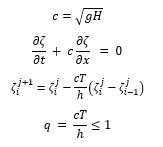

 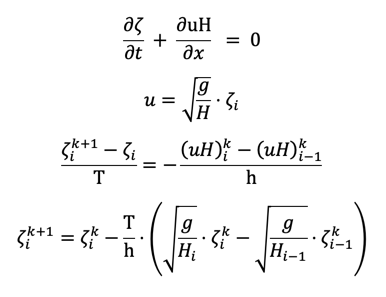

## **Numerical Methods**

*(Describe the numerical methods used: Why did you choose to use these methods?)*

We plan on using the Forward Euler Method as well as the Crank-Nichelson Method. The Forward Euler method was discussed within the research, especially in the scope of constant depth, so we intend to look how results may compare. 

#### Constant Depth

**Forward Euler Method**

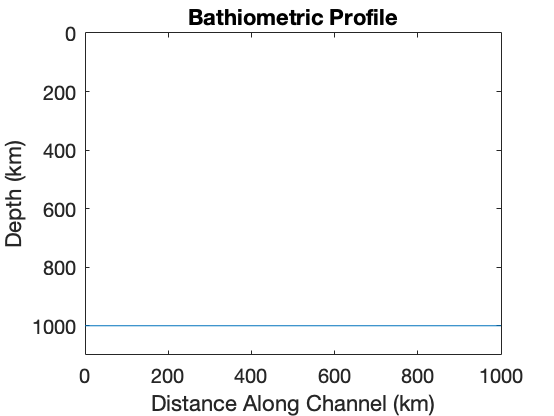

clear; close all; clc;

%Parameters
g = 9.81; %Acceleration due to gravity
H = 1000*10^3; % Constant depth of 1000 m

%Steps
q = 1;
c = sqrt(g*H);
h = 2000;          % m
T = q*h/c;      % seconds 

tf = 300;       % 300 second long analysis
zf = 1000*10^3;      % 1000 km long channel

nt = ceil(tf/T) + 1;
nh = ceil(zf/h) + 1;
h_vec = 0:h:zf;

%Setup Matrix problem
data = [q*ones(nh,1), (1-q)*ones(nh,1)];
M = spdiags(data, -1:0, nh, nh);
Z_con = nan(nh,nt);

%Boundary Condition 
Z_con(1,1) = 1; %no-flux boundary condition
Z_con(1,2) = 0; %no-flux boundary condition
Z_con(2,1) = 0; %no-flux boundary condition

%initial condition
Z_con(:,1) = exp(-0.00000001*(h_vec'-30000).^2);

%Solve matrix problem
for i=1:nt
    Z_con(:,i+1) = M * Z_con(:,i);
    Z_con(1, i+1) = Z_con(2, i+1);
end

figure()
plot([0, 1000], [H/1000, H/1000]);
xlabel('Distance Along Channel (km)')
ylabel('Depth (km)')
title('Bathiometric Profile')
set(gca, 'YDir', 'reverse')
ylim([0 1100])
xlim([0 1000])

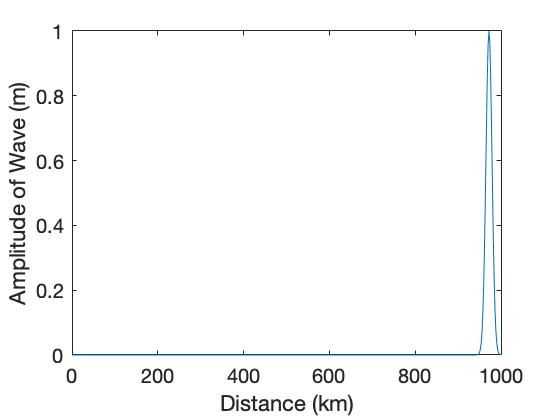


figure()
for i = 1:size(Z_con,2)
    plot(h_vec'/1000, Z_con(:, i));
    pause(0.05);
    xlabel('Distance (km)')
    ylabel('Amplitude of Wave (m)')
    ylim([0 1]);
    xlim([0 1000])
end

#### Crank-Nicholson Method

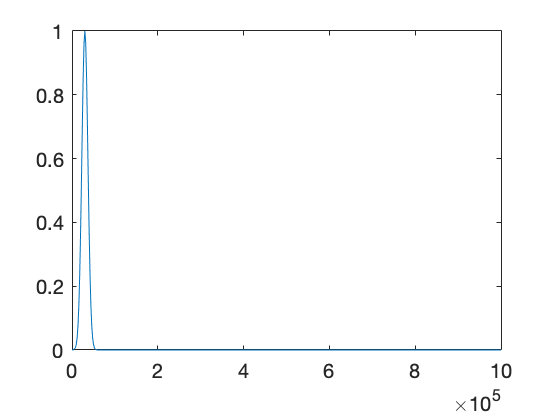

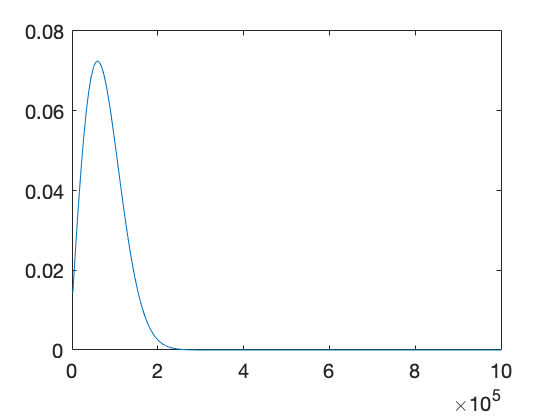

%Parameters
g = 9.81; %Acceleration due to gravity
H = 1000*10^3; % Constant depth of 1000 m


%Steps
q = 1;
c = sqrt(g*H);
h = 2000;  %meters
T = q*h/c; %seconds 

tf = 300;       % 300 second long analysis
zf = 1000*10^3; % 1000 km long channel

nt = ceil(tf/T) + 1;
nh = ceil(zf/h) + 1;
h_vec = 0:h:zf;

%Setup Matrix problem
data = [((0.5*q)*ones(nh,1)), ((1-q)*ones(nh,1)), ((0.5*q)*ones(nh,1))];
data_k1 = [((-0.5*q)*ones(nh,1)), ((1+q)*ones(nh,1)), ((-0.5*q)*ones(nh,1))];
M = spdiags(data, -1:1, nh, nh);
M_k1 = spdiags(data_k1, -1:1, nh, nh);
Z = nan(nh,nt);

%Boundary Condition 
Z(1,1) = 1; %no-flux boundary condition
Z(1,2) = 0; %no-flux boundary condition
Z(2,1) = 0; %no-flux boundary condition

%initial condition - tbd
Z(:,1) = exp(-0.00000001*(h_vec'-30000).^2);

%Solve matrix problem
for i=1:nt
    Z(:, i+1) = M_k1 \ (M * Z(:, i));
    Z(1, i+1) = Z(2, i+1);
end


figure()
xlabel('Distance Along Channel (km)')
ylabel('Depth (km)')
title('Bathiometric Profile')
set(gca, 'YDir', 'reverse')
ylim([0 1100])
xlim([0 1000])

for i = 1:size(Z,2)
    plot(h_vec', Z(:, i));
    pause(0.05);
end

#### Changing Depth 

**Forward Euler Method**

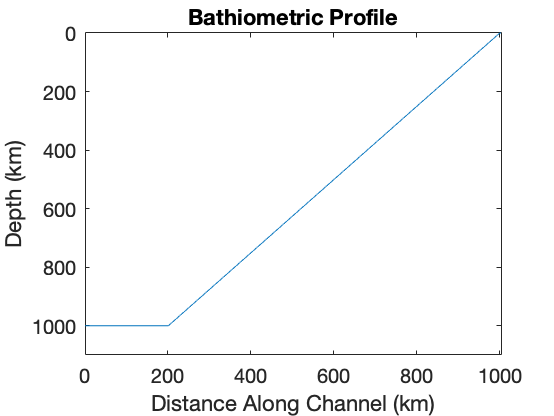

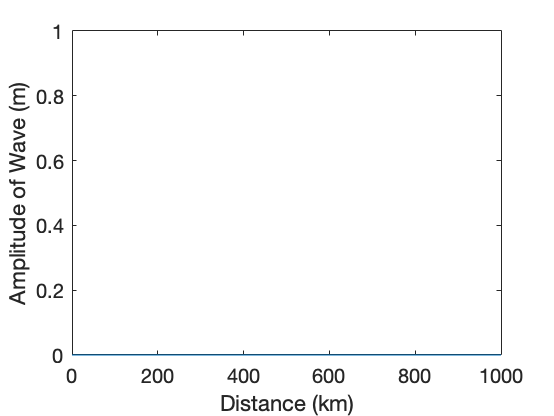

clear H
%Parameters
g = 9.81; %
H(1:201) = 1000 *10^3; %Depth of 1000 m 
H = [H linspace(1000*10^3, 0, 800) 0 0 0];
plot(0:length(H)-1, H/1000);
xlabel('Distance Along Channel (km)')
ylabel('Depth (km)')
title('Bathiometric Profile')
set(gca, 'YDir', 'reverse')
ylim([0 1100])
xlim([0 (length(H)-1)])

%Steps
q = 1;
c = sqrt(g*1000*10^3);
h = 2000; %km
T = q*h/c; %seconds 

tf = 300;
zf = 1000*10^3;
nt = ceil(tf/T) + 1;
nh = ceil(zf/h) + 1;

%Setup Matrix problem
M = zeros(nh,nh);
R = sqrt(g)*T/h;
for i = 1:nh
    M(i, i) = 1 - R*sqrt(H(i*h/1000));
    if i > 1
        M(i, i-1) = R * sqrt(H((i-1)*h/1000));
    end
end

Z_cha = nan(nh,nt);

%Boundary Condition 
Z_cha(1,1) = 1; %no-flux boundary condition
Z_cha(1,2) = 0; %no-flux boundary condition
Z_cha(2,1) = 0; %no-flux boundary condition

%initial condition
Z_cha(:,1) = exp(-0.00000001*(h_vec'-30000).^2);

%Solve matrix problem
for i=1:nt
    Z_cha(:,i+1) = M * Z_cha(:,i);
end

figure()
for i = 1:size(Z_cha,2)
    plot(h_vec', Z_cha(:, i));
    pause(0.05);
    xlabel('Distance (km)')
    ylabel('Amplitude of Wave (m)')
    ylim([0 1]);
    xlim([0 1000])
end

### **Comparison of Constant Depth vs Changing Depth**

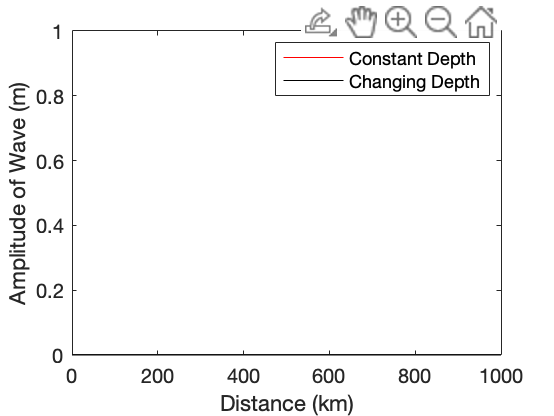

figure()
for i = 1:size(Z_cha,2)
    plot(h_vec', Z_con(:, i), 'r')
    hold on
    plot(h_vec', Z_cha(:, i), 'k');
    pause(0.05);
    xlabel('Distance (km)')
    ylabel('Amplitude of Wave (m)')
    ylim([0 1]);
    xlim([0 1000])
    legend({'Constant Depth', 'Changing Depth'})
    hold off
end

## **Results**

*(What simulations did you run with the model? Describe the results.* *How do the results compare with any known solutions or data?* *How do the results change with different methods, time steps, grid spacing, or model parameters?* *What did the model tell you about the process you were studying?* *How could the model be improved in terms of methods used or processes included**?)*

For this model, we performed three different simulations. The first two simulations were run on a model in which it was assumed that there was constant depth of the ocean floor. The first method used Forward Euler while the second used Crank-Nichelson. 

The Crank-Nichelson method is theoretically a more accurate calculation model that assigns a weighted average (typically 0.5) to both the Forward and Backward Euler schemes. Within our model we notice that the Crank-Nicholson method provides a "less dynamic" model for tidal propagation in comparison to the Forward Euler Method.

Then, we considered how the model would be changed by using varying depth profile rather than a constant depth. These cases may vary in their applications in considering how a wave may propagate out on the open ocean, where changes in depth may be negligible, compared to when a tsunami hits the continental shelf where differences are more extreme. However, our model did not consider the energy changes and momentum from water moving; it consisted of solely the changes in velocity from depth.As a result, the wave is solely motivated by gravity and ends up deaccelerating and dissipating as the wave propagates over shrinking depth. This is unlike what we would expect in real life, as the wave should increase in magnitude and accelerate. Obviously, this model could be improved with the consideration of energy and momentum equations.

When analyzing these seperate models we also looked into the effects of changing the Courant (c) #, and noticed that when the c < 1, the model displayed diffusive behavior and when the c > 1, the model displayed unstable behaviour. This led us to utilize c = 1 as our constant.

## **References**

Kowalik, Z. (2012) Introduction to Numerical Modeling of Tsunami Waves. Institute of Marine Science University of Alaska, Fairbank. 